# Projective Transformation or simple Camera model views

## Parameters:

f = 1/40;

Wdwc = [4;0;0];
CRW = [1 0 0 ;
       0 0 -1;
       0 1 0];  
   

Any point defined in the world frame will be expressed on the camera frame by:


$$$^C{p} = ^CR_W\, ^Wp + ^Cd_{C\to W}$$$


or by using


$$^C \hat{p} =\,  ^CA_W\, ^W \hat{p}$$


In this case

CAW = [CRW -CRW*Wdwc; 0 0 0 1];


which inverse is $^WA_C$ 


WAC = [CRW' Wdwc; 0 0 0 1];

## Lets represent both reference frames on the world reference frame.

xw = [1 0 0]';
yw = [0 1 0]';
zw = [0 0 1]';

ow = [0;0;0];

wxc = WAC*[xw;1];
wxc = wxc(1:3);

wyc = WAC*[yw;1];
wyc = wyc(1:3)

wyc =      4
     0
    -1



wzc = WAC*[zw;1];
wzc = wzc(1:3)

wzc =      4
     1
     0



woc = Wdwc;



Plot the triads

figure1 = figure('Color',[1 1 1]);
PS=get(figure1,'PaperPosition');
PS(1)=0;
PS(2)=0;
PS(3)=PS(3)*.5;
PS(4)=PS(4)*.5;
set(figure1,'PaperPosition',PS);
% Create axes

axes1 = axes('Parent',figure1,...
    'YMinorGrid','off','YGrid','on',...
    'XMinorGrid','off','XGrid','on',...
    'ZMinorGrid','off','ZGrid','on',...
    'GridLineStyle',':','MinorGridLineStyle',':',...
    'XColor',[0.25,0.25,0.25],...
    'YColor',[0.25,0.25,0.25],...
    'ZColor',[0.25,0.25,0.25],...
    'xlim', [-2,12],...
    'ylim', [-2,15],...
    'zlim', [-2,10],...
    'Projection','perspective',...
    'DataAspectRatio',[1 1 1],...
    'FontSize',16);
box(axes1,'on');
view(axes1,[57 20]);
hold(axes1,'all');

xlabel(axes1,'$x$','interpreter','Latex')
ylabel(axes1,'$y$','interpreter','Latex')
zlabel(axes1,'$z$','interpreter','Latex')


Plot the world triad

plot3([ow(1);xw(1)],[ow(2);xw(2)],[ow(3);xw(3)],'Color',[0,1,0],'LineWidth',2);
plot3([ow(1);yw(1)],[ow(2);yw(2)],[ow(3);yw(3)],'Color',[0,1,0],'LineWidth',2);
plot3([ow(1);zw(1)],[ow(2);zw(2)],[ow(3);zw(3)],'Color',[1,0,0],'LineWidth',2);

Plot the Camera triad

plot3([woc(1);wxc(1)],[woc(2);wxc(2)],[woc(3);wxc(3)],'Color',[0,0,1],'LineWidth',2);
plot3([woc(1);wyc(1)],[woc(2);wyc(2)],[woc(3);wyc(3)],'Color',[0,0,1],'LineWidth',2);
plot3([woc(1);wzc(1)],[woc(2);wzc(2)],[woc(3);wzc(3)],'Color',[1,0,0],'LineWidth',2);
drawnow;


## Parallel lines are projected to lines that intersect ar a vanishing point:

the lines given by


$$l_1(\lambda) = x_0 + \lambda v\\
l_2 (\lambda) = x_1 + \lambda v\\$$


are parallel since the share the same director vector.

We can plot two lines by given values to the presented equations. Since every line is represented by 2 points we can select:

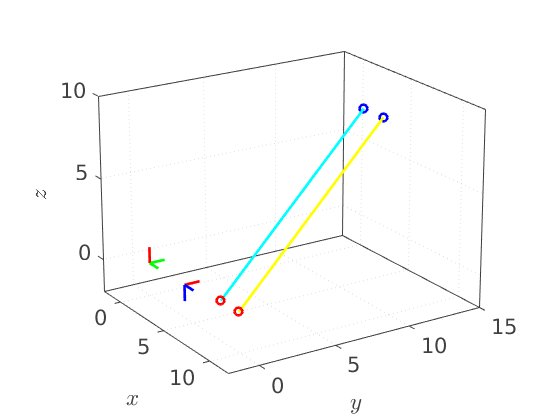

x01 = [3;3;-2];
x11 = [5;3;-2];
v = [0;1;1];

x02 = x01 + 10*v;
x12 = x11 + 10*v;

plot3([x01(1);x02(1)],[x01(2);x02(2)],[x01(3);x02(3)],'Color',[0,1,1],'LineWidth',2);
plot3(x01(1),x01(2),x01(3),'Marker','o','Color',[1,0,0],'LineWidth',2);
plot3(x02(1),x02(2),x02(3),'Marker','o','Color',[0,0,1],'LineWidth',2);
plot3([x11(1);x12(1)],[x11(2);x12(2)],[x11(3);x12(3)],'Color',[1,1,0],'LineWidth',2);
plot3(x11(1),x11(2),x11(3),'Marker','o','Color',[1,0,0],'LineWidth',2);
plot3(x12(1),x12(2),x12(3),'Marker','o','Color',[0,0,1],'LineWidth',2);

We can project these to lines to the camera plane by projecting the extreme points.  

P = [x01 x02 x11 x12];
[Pt] = cameraproj(CAW,f,P)

Pt =    -0.0083   -0.0019    0.0083    0.0019
    0.0167   -0.0154    0.0167   -0.0154


Let's plot these points as lines:

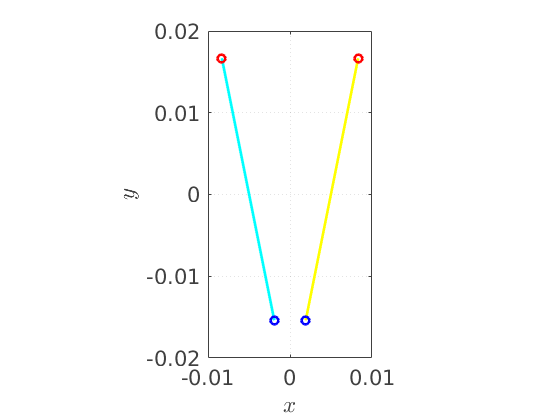

x01t = Pt(:,1);
x02t = Pt(:,2);
x11t = Pt(:,3);
x12t = Pt(:,4);

figure1 = figure('Color',[1 1 1]);
PS=get(figure1,'PaperPosition');
PS(1)=0;
PS(2)=0;
PS(3)=PS(3)*.5;
PS(4)=PS(4)*.5;
set(figure1,'PaperPosition',PS);
% Create axes

axes1 = axes('Parent',figure1,...
    'YMinorGrid','off','YGrid','on',...
    'XMinorGrid','off','XGrid','on',...
    'ZMinorGrid','off','ZGrid','on',...
    'GridLineStyle',':','MinorGridLineStyle',':',...
    'XColor',[0.25,0.25,0.25],...
    'YColor',[0.25,0.25,0.25],...
    'ZColor',[0.25,0.25,0.25],...
    'DataAspectRatio',[1 1 1],...
    'FontSize',16);
box(axes1,'on');
hold(axes1,'all');
plot([x01t(1);x02t(1)],[x01t(2);x02t(2)],'Color',[0,1,1],'Linewidth',2);
plot(x01t(1),x01t(2),'Marker','o','Color',[1,0,0],'LineWidth',2);
plot(x02t(1),x02t(2),'Marker','o','Color',[0,0,1],'LineWidth',2);
plot([x11t(1);x12t(1)],[x11t(2);x12t(2)],'Color',[1,1,0],'Linewidth',2);
plot(x11t(1),x11t(2),'Marker','o','Color',[1,0,0],'LineWidth',2);
plot(x12t(1),x12t(2),'Marker','o','Color',[0,0,1],'LineWidth',2);
xlabel(axes1,'$x$','interpreter','Latex')
ylabel(axes1,'$y$','interpreter','Latex')